%Initialization

message = 10^7;
M = 4;
message_symb = message/log2(M);
nc = 400;
rand_bit = randi([0 1], message_symb, log2(M));

IFFT_point = 1024;
darkpurple = [170 149 200]./256;
lightpurple = [221, 217, 245]./256;

%Implementation

#### a) BER for:

- SNR Level = 40 dB

- Clipping Level = 3 dB

- IFFT length = 1024

- num_carriers = 400


SNR = 40;
clp_lvl = 3;
AWGN_channel = 0;
BER = OFDM(rand_bit, nc, IFFT_point, SNR, clp_lvl, AWGN_channel)

BER = 0.0105

#### b) BER, SER over SNR (dB) 

- Clipping Level = 3 dB

- IFFT length = 1024

- num_carriers = 400

BER_v_SNR = zeros(1, 30);
SER_v_SNR = zeros(1, 30);

for snr = 1:30
    [BER_v_SNR(snr), SER_v_SNR(snr)] = OFDM(rand_bit, nc, IFFT_point, 20+snr, clp_lvl, AWGN_channel);
end

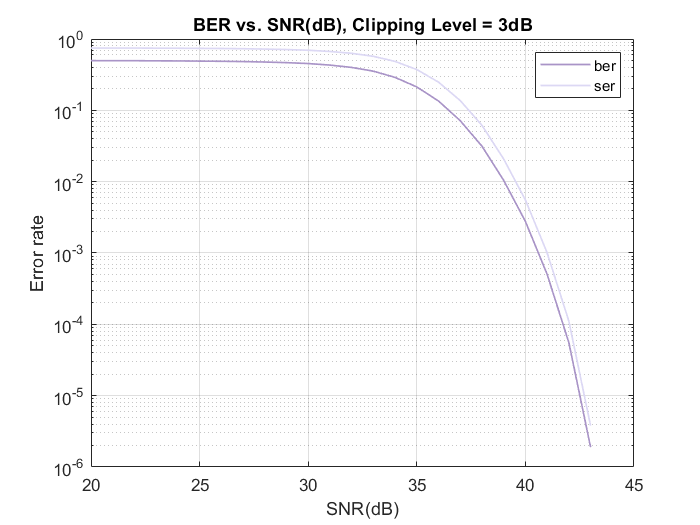

figure
s = semilogy(20:49,BER_v_SNR);
s.Color = darkpurple;
s.LineWidth = 1;
hold on
s = semilogy(20:49, SER_v_SNR);
s.Color = lightpurple;
s.LineWidth = 1;
legend('ber','ser')
grid on
xlabel("SNR(dB)")
ylabel('Error rate')
title("BER vs. SNR(dB), Clipping Level = 3dB")

#### c) BER, SER over Clipping Level (dB) 

- SNR Level = 40 dB

BER_v_clip = zeros(1,20);
SER_v_clip = zeros(1,20);

SNR = 40;

for clip = 1:20
    [BER_v_clip(clip), SER_v_clip(clip)] = OFDM(rand_bit, nc, IFFT_point, SNR, clip, AWGN_channel);
end

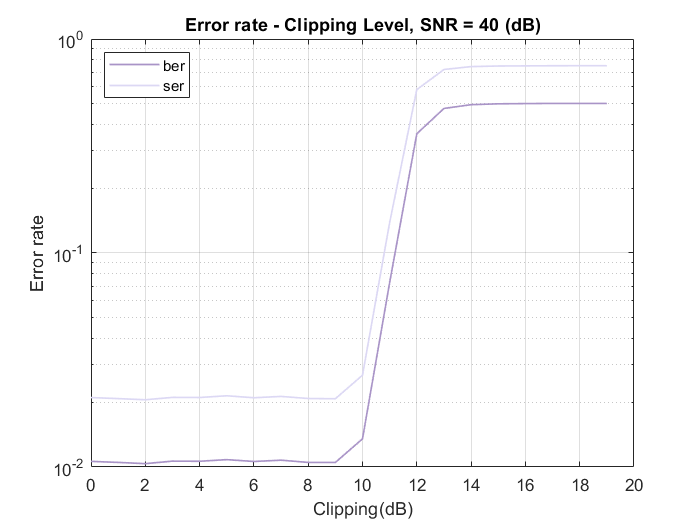

figure
s = semilogy(0:19,BER_v_clip);
s.Color = darkpurple;
s.LineWidth = 1;
hold on
s = semilogy(0:19, SER_v_clip);
s.Color = lightpurple;
s.LineWidth = 1;
legend('ber','ser', 'Location', 'northwest')
grid on
xlabel("Clipping(dB)")
ylabel('Error rate')
title("Error rate - Clipping Level, SNR = 40 (dB)")

#### d) BER over SNR (dB) for Rayleigh Fading Channel

- Clipping Level = 3 dB

rayleigh_channel = 1;
BER_rayleigh = zeros(1,30);
for snr = 1:30
    BER_rayleigh(snr) = OFDM(rand_bit, nc, IFFT_point, 20+snr, clp_lvl, rayleigh_channel);
end

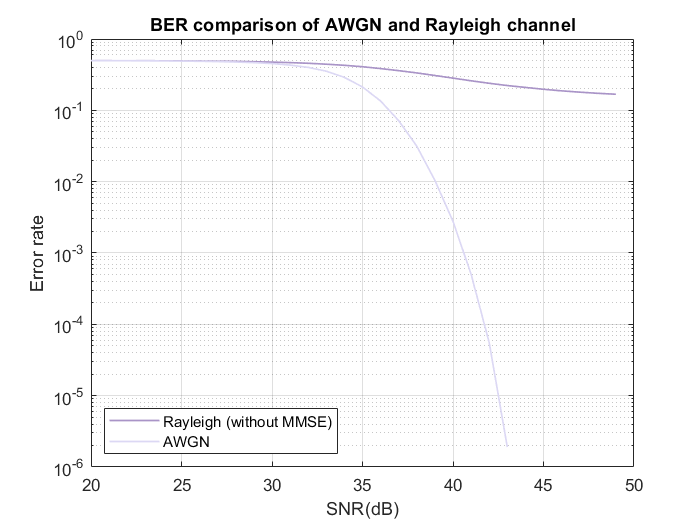

figure
s = semilogy(20:49,BER_rayleigh);
s.Color = darkpurple;
s.LineWidth = 1;
hold on
s = semilogy(20:49, BER_v_SNR);
s.Color = lightpurple;
s.LineWidth = 1;

legend('Rayleigh (without MMSE)','AWGN','Location','southwest')
grid on
xlabel("SNR(dB)")
ylabel('Error rate')
title("BER comparison of AWGN and Rayleigh channel")

#### e) BER over SNR (dB) for Rayleigh + MMSE Equalizer

- Clipping Level = 3 dB

rayleigh_channel_MMSE = 2;
BER_rayleigh_MMSE = zeros(1,30);
for snr = 1:30
    BER_rayleigh_MMSE(snr) = OFDM(rand_bit, nc, IFFT_point, 20+snr, clp_lvl, rayleigh_channel_MMSE);
end

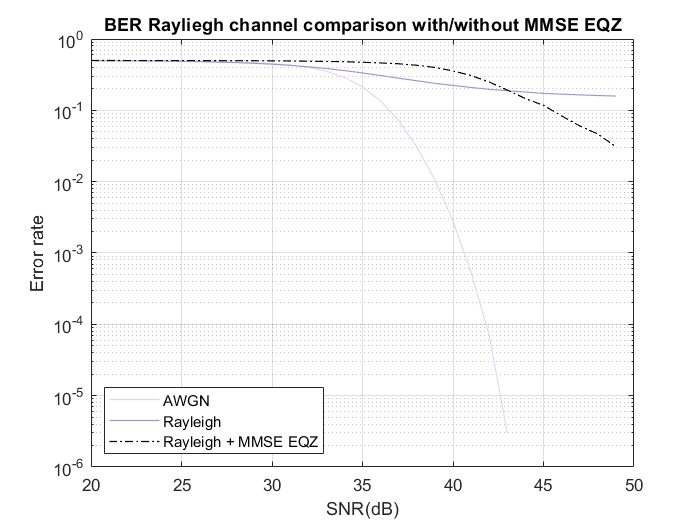

figure
s = semilogy(20:49, BER_v_SNR);
s.Color = lightpurple;
s.LineWidth = 0.7;
hold on

s = semilogy(20:49,BER_rayleigh);
s.Color = darkpurple;
s.LineWidth = 0.7;
hold on

s = semilogy(20:49, BER_rayleigh_MMSE);
s.Color = 'k';
s.LineWidth = 0.7;
s.LineStyle = "-.";


legend('AWGN', 'Rayleigh','Rayleigh + MMSE EQZ','Location', 'southwest')
grid on
xlabel("SNR(dB)")
ylabel('Error rate')
title("BER Rayliegh channel comparison with/without MMSE EQZ")

AWGN v.s Rayleigh + MMSE in Zoomed mode:

ber_SNR_zoomed = zeros(1,21);
ber_rayl_eq_zoomed = zeros(1,21);

for snr = 0:20
    ber_SNR_zoomed(snr+1) = OFDM(rand_bit, nc, IFFT_point, 41+snr/5, clp_lvl, AWGN_channel);
    ber_rayl_eq_zoomed(snr+1) = OFDM(rand_bit, nc, IFFT_point, 41+snr/5, clp_lvl, rayleigh_channel_MMSE);
end

% figure;
% s = semilogy(41:0.2:45, ber_SNR_zoomed);
% s.Color = 'k';
% s.LineWidth = 0.7;
% s.LineStyle = "-.";
% hold on
% 
% 
% s = semilogy(41:0.2:45,  ber_rayl_eq_zoomed);
% s.Color = darkpurple;
% s.LineWidth = 0.7;
% 
% legend('AWGN','Rayleigh + MMSE EQZ','Location', 'southwest')
% grid on
% xlabel("SNR(dB)")
% ylabel('Error rate')
% title("BER comparison - AWGN v.s Rayleigh + MMSE (zoomed)")

**Bonus**

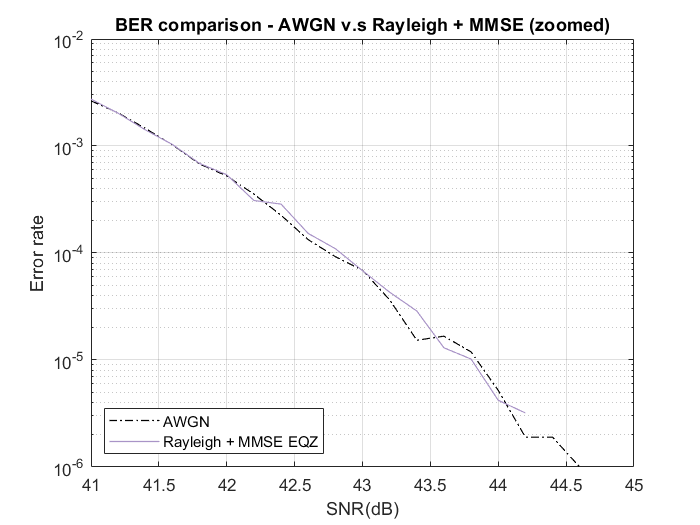

BER_bonus = 0;

SER_bonus = 0;
[BER_bonus,SER_bonus, v, Lags] = OFDM(rand_bit, nc, IFFT_point, SNR, clp_lvl, AWGN_channel);

figure;
s = semilogy((Lags), real(v));
s.Color = lightpurple;
s.LineWidth = 0.7;

xlabel("Time separation from pilot string");
ylabel('Correlattion ');
title("Correlation over time");


BER_bonus = zeros(1,30);

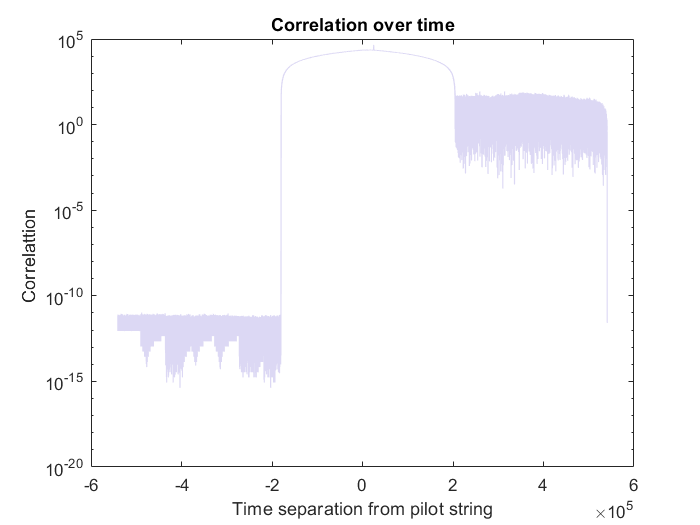

for snr = 1:30
    BER_bonus(snr) = OFDM(rand_bit, nc, IFFT_point, 20+snr, clp_lvl, AWGN_channel);

end


AWGN_channel = 0

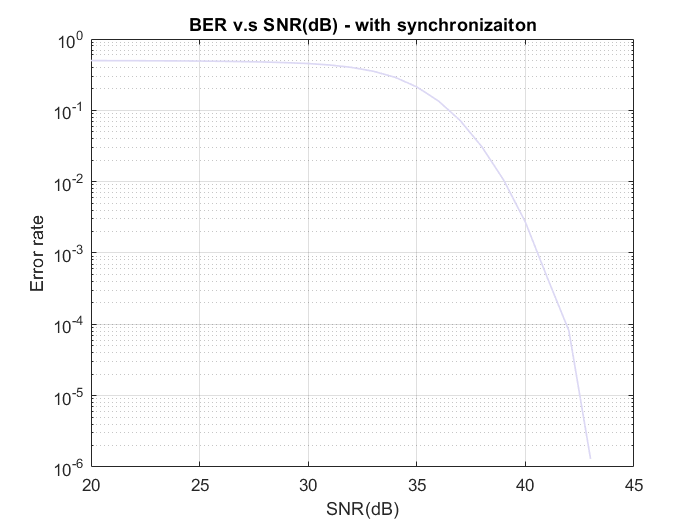

figure;
s = semilogy(20:49,BER_bonus);
s.Color = lightpurple;
s.LineWidth = 1;


grid on;
xlabel("SNR(dB)");
ylabel('Error rate');
title("BER v.s SNR(dB) - with synchronizaiton");